## Opg 1


a = [1, 1, 1]

a =      1     1     1



b = [1, 2, 1]

b =      1     2     1



cross(a, b)

ans =     -1     0     1



cross(a, cross(a, b))

ans =      1    -2     1



cross(cross(a,b), cross(a,b))

ans =      0     0     0


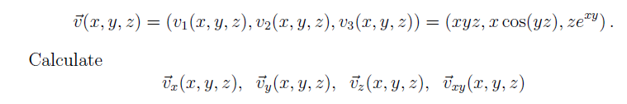

clear
syms x y z
v(x,y,z) = [x*y*z, x*cos(y*z), z*exp(x*y)]

$$v(x, y, z) = \left(\begin{array}{ccc} x\,y\,z & x\,\cos\left(y\,z\right) & z\,{\mathrm{e}}^{x\,y} \end{array}\right)$$


diff(v(x,y,z), x)

$$ans = \left(\begin{array}{ccc} y\,z & \cos\left(y\,z\right) & y\,z\,{\mathrm{e}}^{x\,y} \end{array}\right)$$

diff(v(x,y,z), y)

$$ans = \left(\begin{array}{ccc} x\,z & -x\,z\,\sin\left(y\,z\right) & x\,z\,{\mathrm{e}}^{x\,y} \end{array}\right)$$

diff(v(x,y,z), z)

$$ans = \left(\begin{array}{ccc} x\,y & -x\,y\,\sin\left(y\,z\right) & {\mathrm{e}}^{x\,y} \end{array}\right)$$

v_x = diff(v(x,y,z), x)

$$v\_x = \left(\begin{array}{ccc} y\,z & \cos\left(y\,z\right) & y\,z\,{\mathrm{e}}^{x\,y} \end{array}\right)$$


diff(v_x, y)

$$ans = \left(\begin{array}{ccc} z & -z\,\sin\left(y\,z\right) & z\,{\mathrm{e}}^{x\,y}+x\,y\,z\,{\mathrm{e}}^{x\,y} \end{array}\right)$$

clear
c = [1,1,0]

c =      1     1     0


b = [1,0,0]

b =      1     0     0



r = @(t)c+t^2*b

r = function_handle with value:
    @(t)c+t^2*b


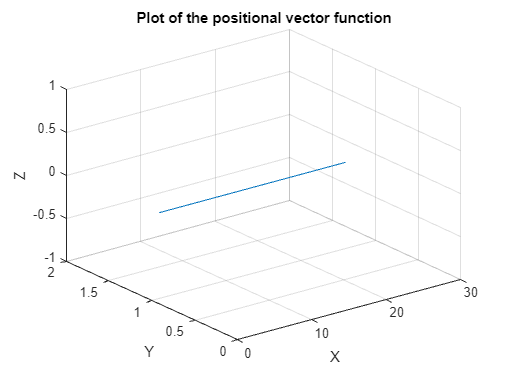



DrawVectorPositionPath3D(r, 0, 5, 100)

clear
c = [1, 1, 0]

c =      1     1     0


b = [1, 0, 0]

b =      1     0     0


syms t 
r(t) = c+t^2 * b

$$r(t) = \left(\begin{array}{ccc} t^{2}+1 & 1 & 0 \end{array}\right)$$


r_v = diff(r, t)

$$r\_v(t) = \left(\begin{array}{ccc} 2\,t & 0 & 0 \end{array}\right)$$


r_a = diff(r_v, t)

$$r\_a(t) = \left(\begin{array}{ccc} 2 & 0 & 0 \end{array}\right)$$

clear
syms t real
assume (t > 0);
r_v = [2*t, 0, 0]

$$r\_v = \left(\begin{array}{ccc} 2\,t & 0 & 0 \end{array}\right)$$

r_a = [2, 0, 0]'

r_a =      2
     0
     0



p = simplify(dot(r_a, r_v)/norm(r_v))

$$p = 2$$